clc; clear;

figure;
metric = 'SSIM';

file_name = ".\epoch1000\" + metric + ".txt"

file_name = ".\epoch1000\SSIM.txt"

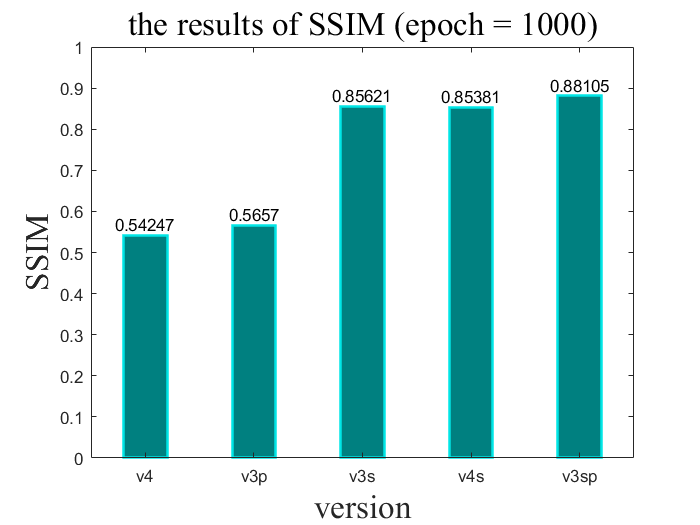

m = load(file_name);

X = categorical({'v4', 'v3p', 'v3s', 'v4s', 'v3sp'});
X = reordercats(X,{'v4', 'v3p', 'v3s', 'v4s', 'v3sp'});
b = bar(X, m, 0.4, 'FaceColor',[0 .5 .5],'EdgeColor',[0 .9 .9],'LineWidth',1.5);

ylim([0, 1]);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

% 设置图片各项属性
key = {'FontSize', 'FontName'};
value = {20, 'Times New Roman'};

title_name = "the results of " + metric + " (epoch = 1000)";
title(title_name, 'FontSize', 20, 'FontName', 'Times New Roman');

xlb = xlabel("version");
ylb = ylabel(metric);
set([xlb, ylb], key, value);


% axis square;